# Superpixel Clustering of 3D Vasculature

## 1. Introduction

The confocal images provided are essentially a stack of 2D grayscale images, where every 3D cartesian coordinate represents a voxel. Earlier segmentation resuts were obtained by morphologically altering each layer and recombining the 3D stack to form a binary 3D-array that represented segmented vasculature. This method, while it works, disregards differences in layers and performs the same morphological operation on each layer.

The new proposed method involves involves formation of superpixels from voxels using a simple linear iterative clustering (SLIC) algorithm. This algorithm groups individual voxels into clusters with similar size (local clustering). The advantage here is that boundaries of vasculature are well delianted even in low SNR, thus allowing accurate segmentation.

## 2. Initialize Data

Let's of course start off by clearning the MATLAB workspace prior to any computations:

clc;
clear all;
close all;
warning off;

We'll first open a 3D volume and apply padding of 3 voxels in each dimension. Then obtain it's size parameters X, Y and Z, and establish voxel resolution given by *resX*, *resY*, *resZ*.

I = load('MATLAB_Converted/Multiphoton/MS2.mat');
I = I.catI;
I = double(I);
I = padarray(I,[3 3],0,'both');  % Apply 3-voxel padding to each dimension
[X Y Z] = size(I);
resX = 0.82; % X-Resolution in um
resY = 0.82; % Y-Resolution in um
resZ = 2.0;  % Z-resolution in um

We can visualize this volume using the *slice* function:

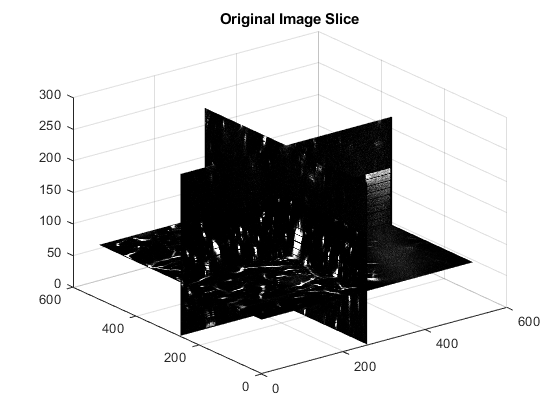

figure;
slice(double(I),X/2,Y/2,Z/3), title('Original Image Slice')
grid on, shading interp, colormap gray;

## 3. Image Preprocessing

It is very important to preprocess the image to minimize noise so that a high SNR can be maintained. To do this, we apply some filters.

The first filter is a Tophat filter, which removed global uneven illumination in image. At the same time, a contrast-limited adaptive histogram equalization (CLAHE) is performed to enhance contrast of each layer and revel hidden details. We do this process on a layer-by-layer basis.

UPDATE: Independent planar filters will be removed as they don't scale on anisotropic data. It has been included here however to demonstrate planar filters

R_SE1 = 50;                             % Tophat structuring element radius
SE1 = strel('disk', R_SE1);             % SE For Tophat

filteredI = zeros(size(I));             % Initialize filtered matrix
bufferI = zeros(size(I,1),size(I,2));   % initialize buffer matrix
for idxLayer = 1:Z
    bufferI = I(:,:,idxLayer);
    tophatI = imtophat(bufferI,SE1);    % Tophat filtering
    eqI = adapthisteq(tophatI);         % CLAHE
    filteredI(:,:,idxLayer) = eqI;      % Writing filtered layers to initialized matrix
end

We can visualize the difference between original image and filtered morphologically filtered layer. The original image is on left and enhanced on right:

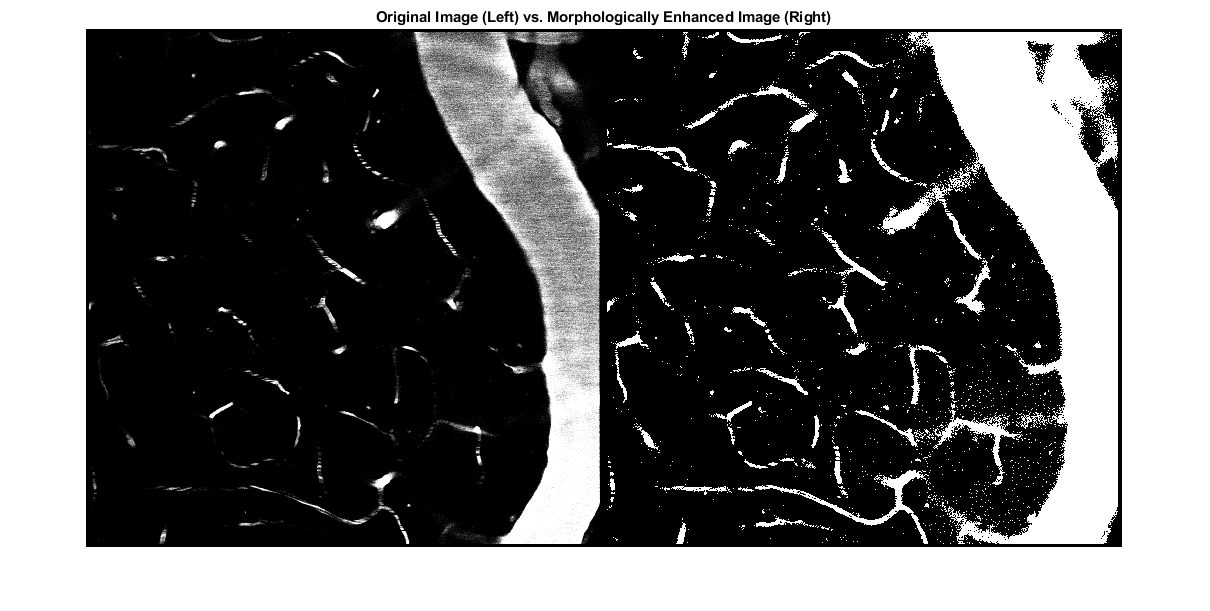

figure;
imshowpair(I(:,:,170),filteredI(:,:,170),'montage');
title('Original Image (Left) vs. Morphologically Enhanced Image (Right)')

Next, we apply median and mean filtering in a 3 x 3 x 3 neighborhood to minimize noisy voxels and enhace SNR even further.

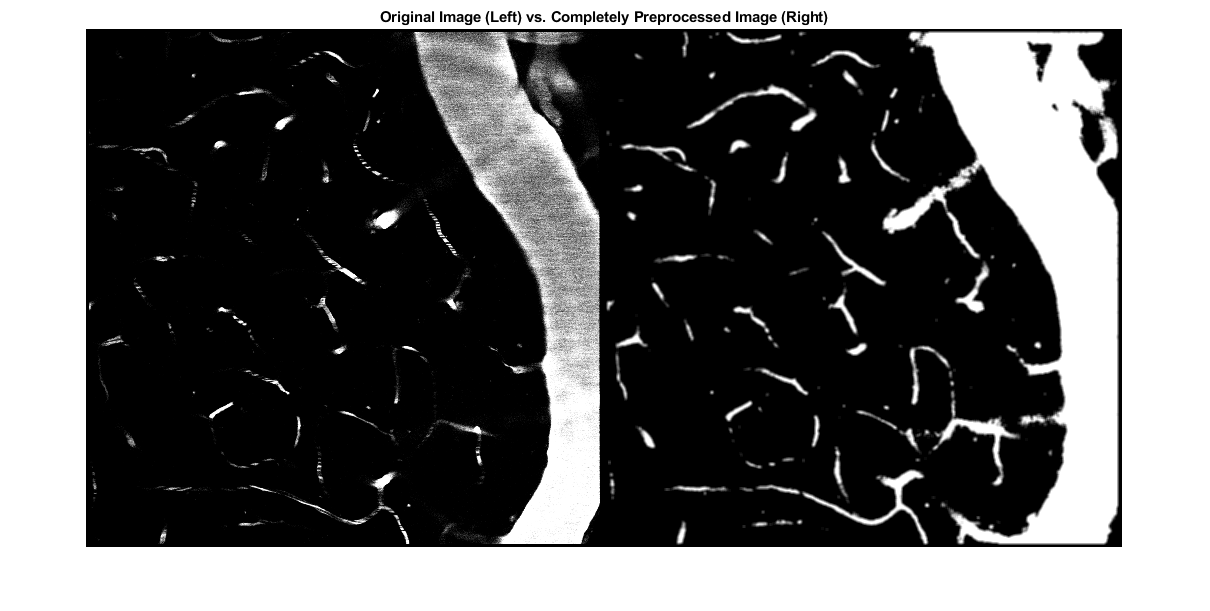

filtNeigh = [3 3 3];                            % Define filter neighborhood size
filteredI = medfilt3(filteredI, filtNeigh);     % Apply a 3D median filter
filteredI = imboxfilt3(filteredI, filtNeigh);   % Apply a 3D mean filter

figure;                                         % Vizualize image enhancements
imshowpair(I(:,:,170),filteredI(:,:,170),'montage');
title('Original Image (Left) vs. Completely Preprocessed Image (Right)')

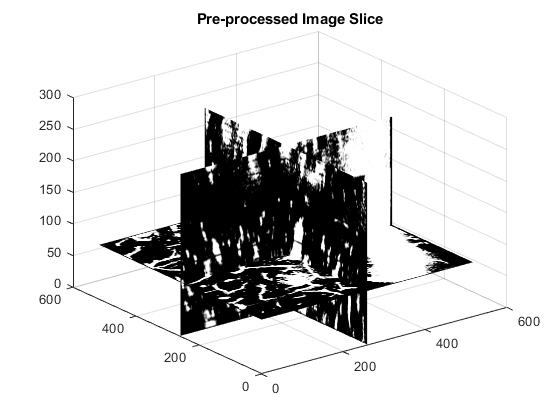


figure;
slice(filteredI,X/2,Y/2,Z/3), title('Pre-processed Image Slice')
grid on, shading interp, colormap gray;

The difference between the starting image and pre-processed image is vast. Tiny pixels which were most likely noise have been eliminitated, while smoothing of vasculature edges. It is also evident that SNR has greatly improved.

## 4. Superpixel Clustering

The completion of preprocessing step paves for superpixel clustering. This can be done in a single line of code in MATLAB.

The superpixel algorithm in MATLAB requires an input on the number of superpixels to form, and we do not want this to be too little or too high as it will lead to under-clustering and over-clustering respectively. I arbtrarily calculated this number using the formula $3\times \sqrt{\mathrm{XYZ}}$, which automatically scales the number of clusters to image size. Any decimal values are rounded up to the nearest whole number.

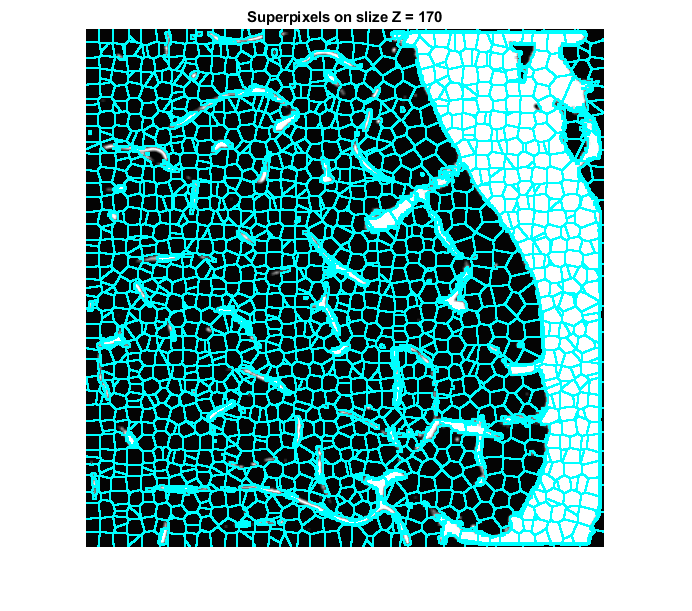

nSuperPx = ceil(sqrt(X*Y*Z))*3;               % Define no. of superpixels to generate

%   Calculate superpixels in 3D. L here refers to a labelled 3D matrix defining superpixels
%   and N is the actual number of superpixels defined.
[L,N] = superpixels3(filteredI,nSuperPx,'Method','slic');

% Convert superpixels into boundary masks
pixelBW = zeros(size(I));
for plane = 1:Z
    BW = boundarymask(L(:,:,plane));
    pixelBW(:,:,plane) = BW;
end

% Visualize superpixel clustering
imPlusBoundary = imoverlay(filteredI(:,:,170),double(pixelBW(:,:,170)),[0 1 1]);
figure;
imshow(imPlusBoundary),title('Superpixels on slize Z = 170')

The figure above shows superpixels on an a slice of the pre-processed image. Given this sample, we can infer the following featuers for wholesome segmentation:

- For a superpixel bounding vascular region, the average local intensity will be greater than a superpixel containing avascular region. The average local intensity is defined as mean of voxel intensities in a given local region. In mathematical terms, if $I_i \text{ }$denotes the average intensity inside a given local region $S_i \text{ },$$I_j$ denotes the intensity of voxel $k$ and ${\mathrm{VS}}_i$ denotes all voxels inside superpixel, an the average local intensity is derived as:$I_i =\frac{\Sigma_{k\in {\mathrm{VS}}_i } I_j }{N_i }$

- Superpixels bounding a vascular region are shaped differently from those bounding avascular region. The absence of any voxels in avascular regions results in consistently square-shaped superpixels that have almost no variation in shape irregualarity. Shape irregularity simply quantifies textural feature of a superpixel. In mathematical terms, if $A_i \text{ }$is the surface area of a local region $S_i$, and its volume is $V_i$, the shape irregularity is ${\mathrm{SI}}_i =\frac{A_i }{V_i }$. The contrary will be true for superpixels bounding vascular region because their irregular shape. One can expect shape irregularity to be much higher for vascular regions than avascular regions.

- Consistent orientation for vascular regions than avascular regions. Least absolute eigenvalues can be derived per voxel from a Hessian matrix analysis, and denoted by $\left({\mathrm{dx}}_k ,{\mathrm{dy}}_k ,{\mathrm{dz}}_k \right)$ for $k=1,2,3,\ldotp \ldotp \ldotp ,N$, where $N$ is the number of voxels the vascular group and ${\mathrm{VS}}_i$ are all voxels inside bounded region. Every local region $S_i$ can be assigned an orientation vector

 
$${\theta x}_i =\frac{\Sigma_{k\in {\mathrm{VS}}_i } {\mathrm{dx}}_k }{N_i },{\theta y}_i =\frac{\Sigma_{k\in {\mathrm{VS}}_i } {\mathrm{dy}}_k }{N_i },{\theta z}_i =\frac{\Sigma_{k\in {\mathrm{VS}}_i } {\mathrm{dz}}_k }{N_i }$$


            We would expect vasular regions to have greater consistent orientation due to the absence of noise.

## 5. Features 1 and 2 - Average Intensity and Shape Irregularity

With superpixel regions defined, it is relatively straight-forward to derive the two features above. We can call *regionprops3 *to compute the intermediary features to obtain the actual feature values. Variables *averageIntensity *and *shapeIrregularity *contain the two of the three desired features for each superpixel.

pixelIdxList = label2idx(L);           % Assign ID to each supervoxel in the image

% Form a 'stats' table containing intermediary and desired features
stats = regionprops3(L,filteredI,'Centroid','EigenValues','MeanIntensity','SurfaceArea',...
    'Volume','VoxelIdxList');

% Form data vectors containing features
averageIntensity = stats.MeanIntensity;
shapeIrregularity = stats.SurfaceArea./stats.Volume;

Now that we have two features, we can do a scatter plot to see how well our two classes (vascular and avascular) separate. In fact, we can even cluster them into two clusters to better visualize separation of classes.

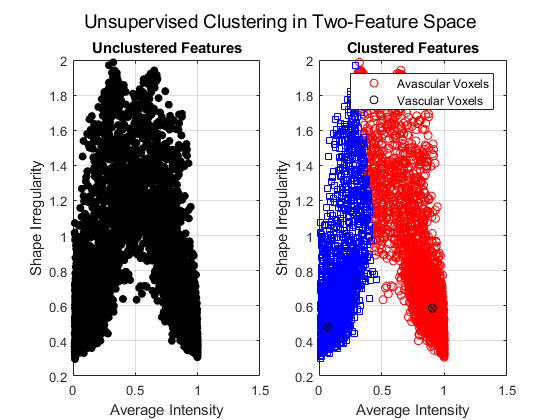

k = 2;          % No. of clusters
[cidx cmeans] = kmeans([averageIntensity shapeIrregularity]...
    ,k,'dist','sqeuclidean');

clustPlotColors = {'ro','bs'};
figure;
subplot(121), scatter(averageIntensity,shapeIrregularity,36,'k','filled');
xlabel('Average Intensity');
ylabel('Shape Irregularity');
title('Unclustered Features')
box on, grid on;

subplot(122);
for kLoop = 1:k
    clust = find(cidx==kLoop);
    hold on;
    plot(averageIntensity(clust),shapeIrregularity(clust),clustPlotColors{kLoop});
    plot(cmeans(:,1),cmeans(:,2),'ko');
    plot(cmeans(:,1),cmeans(:,2),'kx');
    xlabel('Average Intensity');
    ylabel('Shape Irregularity');
    title('Clustered Features')
    hold off;
end
box on, grid on;
legend('Avascular Voxels','Vascular Voxels')
title('Clustered Features')
suptitle('Unsupervised Clustering in Two-Feature Space')

Unsupervised clustering shows two distinct centroids, indicating that there are indeed two distinct classes of voxels in this image - vascular and avascular. While it may be hard to discern between classes in unscattered data, the addition of a third feature to create a three-feature space may produce excellent centroid separation for unsupervised classification of voxels and hence highly-accurate segmentation.

## 6. Feature 3 - Orientation Consistency

This feature identifies the orientation of each voxel. In vascular regions, we'd expect to see consistency in orientation as most voxels are filled. For avascular pixels, the presence of noise will throw this feature off and produce an orientation that is lower in magnitude relative to vascular voxels.

We derive this feature by first computing the Hessian matrix of all voxels in this image. The Hessian matrix is a square matrix of the second partial derivatives of a voxel, and is defined by:

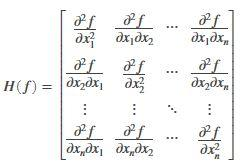

MATLAB has a built-in function called *gradient* which computes the numerical gradient, and calling this function twice will produce second-order partial derivative. In the code snippt below, we are only concerned with the *Dxx, Dyy, *and *Dzz *all other first-order derivative are removed to save memory. The feature vector is named *ortConsistency.*

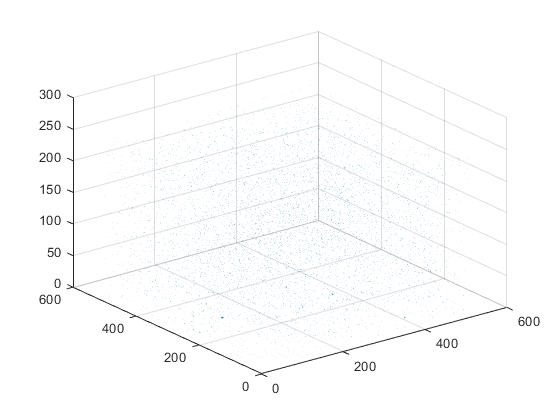

% Compute first-order derivatives
[Dx Dy Dz] = gradient(filteredI);

% Compute second-order derivatives
[Dxx Dyx Dzx] = gradient(Dx);
[Dxy Dyy Dzy] = gradient(Dy);
[Dxz Dyz Dzz] = gradient(Dz);
clear Dx Dy Dz

% Calculate eignevalues
[Lambda1,Lambda2,Lambda3,Vx,Vy,Vz] = eig3volume(Dxx,Dxy,Dxz,Dyy,Dyz,Dzz);

% Calculate absolute values of eigenvalues
LambdaAbs1 = abs(Lambda1);
LambdaAbs2 = abs(Lambda2);
LambdaAbs3 = abs(Lambda3);

% Compute orientation consistency per superpixel
ortConsistency = zeros([N 3]);
for ortLoop = 1:N       % Loop along all superpixels
    for gradLoop = 1:3  % Loop along three gradients
        % Define crietria for selecting appropriate gradient direction
        if gradLoop == 1
            gradRegion = LambdaAbs1(stats.VoxelIdxList{ortLoop});
        elseif gradLoop == 2
            gradRegion = LambdaAbs2(stats.VoxelIdxList{ortLoop});
        elseif gradLoop == 3
            gradRegion = LambdaAbs3(stats.VoxelIdxList{ortLoop});
        end
        numVoxels = numel(stats.VoxelIdxList{ortLoop});
        ortConsistency(ortLoop,gradLoop) = sum(gradRegion)/numVoxels;
    end
end

% Testing method for new eignenvalue using regionsprops3: EigenValues
eigenvalues = stats.EigenValues;
for i = 1:N
    for j = 1:3
        eigs = eigenvalues{i};
        eigVal(i,j) = eigs(j);
    end
end
centroids = stats.Centroid;
figure, quiver3(centroids(:,1),centroids(:,2),centroids(:,3),...
    eigVal(:,1),eigVal(:,2),eigVal(:,3));

Now that we have orientation consistence per superpixel, let's cluster the gradient directions themselves. Each direction vector now represents a feature on its own, resulting in a total of three features.

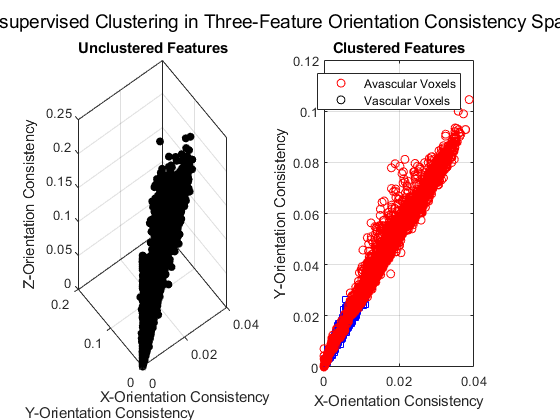

[cidx2 cmeans2] = kmeans([ortConsistency(:,1) ortConsistency(:,2) ortConsistency(:,3)]...
    ,k,'dist','sqeuclidean');

figure;
subplot(121), scatter3(ortConsistency(:,1),ortConsistency(:,2),ortConsistency(:,3), ...
    36,'k','filled');
xlabel('X-Orientation Consistency');
ylabel('Y-Orientation Consistency');
zlabel('Z-Orientation Consistency');
title('Unclustered Features')
box on, grid on;

subplot(122);
for kLoop = 1:k
    clust = find(cidx2==kLoop);
    hold on;
    plot3(ortConsistency(clust,1),ortConsistency(clust,2),ortConsistency(clust,3),...
        clustPlotColors{kLoop});
    plot3(cmeans2(:,1),cmeans2(:,2),cmeans2(:,3),'ko');
    plot3(cmeans2(:,1),cmeans2(:,2),cmeans2(:,3),'kx');
xlabel('X-Orientation Consistency');
ylabel('Y-Orientation Consistency');
zlabel('Z-Orientation Consistency');
    title('Clustered Features')
    hold off;
end
box on, grid on;
legend('Avascular Voxels','Vascular Voxels')
title('Clustered Features')
suptitle('Unsupervised Clustering in Three-Feature Orientation Consistency Space');

This time round the classes don't seem very well separated, but this is to be expected becase the orientation consistency is a feature on its own and cannot be split up to form a three-feature space. 

## 7. Define Global Coordinate System

centroids = stats.Centroid;

Error using matlab.graphics.axis.Axes/get
Operation terminated by user

Error in title (line 54)
   h = get(ax,'Title');

figure, quiver3(centroids(:,1),centroids(:,2),centroids(:,3),...
    ortConsistency(:,1),ortConsistency(:,2),ortConsistency(:,3));
[x,y,z] = meshgrid(1:X,1:Y,1:Z);
figure, 
quiver(x(:,:,170),y(:,:,170),LambdaAbs1(:,:,170),LambdaAbs2(:,:,170));

## 8. Plotting Voxels

Note: Running *'surfc'*  crashes my workstation. Need to find a better way to visualize voxels and orientation.

% for pixels = 1:N
%     coords = pixelIdxList{pixels};
%     quiver3(x,y,z,LambdaAbs1,LambdaAbs2,LambdaAbs3);
%     surfc(filteredI(pixelIdxList{1}))
% end

## 7. Upcoming Implementations

I have to implement an unsupervised classifier that labels each superpixel such that


$$S_i =\left\lbrace \begin{array}{cc}
1 & \mathrm{for}\text{ }\mathrm{superpixels}\text{ }\mathrm{containing}\text{ }\mathrm{vascular}\text{ }\mathrm{voxels}\\
0 & \mathrm{for}\text{ }\mathrm{superpixels}\text{ }\mathrm{containing}\text{ }\mathrm{avascular}\text{ }\mathrm{voxels}
\end{array}\right.$$


This entire algorithm essentialy analyses every voxel in the 3D image and clusters them based on SLIC superpixels, and deduces whether a superpixels is vascular or not. The algorithm will create a binary volume showing the regions of image where only vessels are located.

I have the following things I need to accomplish for this to work:

- Reform 3D stacked image from assigned voxel IDs

- Draw sliced plots showing voxel orientations

- Dimensionality reduction (PCA?) on orientation consistency feature

## 8. Feature Extraction

Following segmentation, the entire remnant 3D binary matrix can be "shrunk" down to a 3D skeleton, which will immediately revel centerlines. All our features are derived from centerline. End poins and break points are very easy to compute using a 3 x 3 x 3 neighborhood lookup matrix.